# t_wvfMTF

Relating the different units and terms used to characterize optics requires some computing and a lot of checking.  In this script we illustrate some of the ways the ISETBio tools help you relate the defocus in diopters to changes in the MTF, 

ieInit

## Create the diffraction-limited wavefront object

wvf0 = wvfCreate;
wave = 550;
wvf0 = wvfSet(wvf0, 'measured wavelength', 550);
wvf0 = wvfSet(wvf0, 'calc wavelengths', 550);
wvf0 = wvfComputePSF(wvf0);


## Vary defocus and plot a slice through the PSF

Set the defocus in diopters by adjusting the Zernike polynomial term for 'defocus'.  We recompute the PSF and plot a slice through the PSF function.

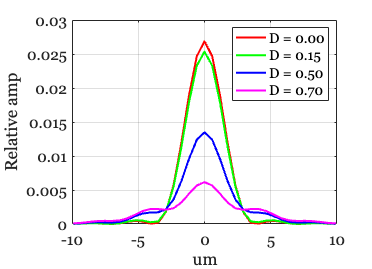

ieNewGraphWin;
d = [0 , 0.15, 0.5, 0.7];
thisL = cell(length(d),1);
for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});
    wvf1 = wvfComputePSF(wvf1);
    wvfPlot(wvf1, '1d psf space', 'um', wave, 10, 'nowindow');
    hold on;
    thisL{ii} = sprintf('D = %0.2f',d(ii));
end

hold off
xlabel('um'); ylabel('Relative amp'); grid on
legend(thisL);

## Compare the two PSFs

Defocus of 0 and 0.5 diopters

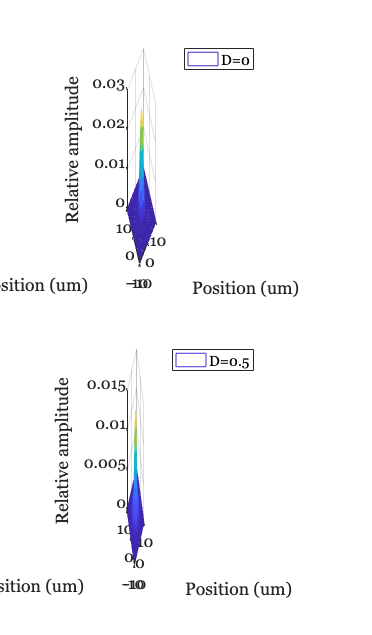

ieNewGraphWin([],'tall');
subplot(2,1,1);
wvfPlot(wvf0, 'psf space', 'um', wave, 10,'no window');
legend({'D=0'})

thisD = d(3);
subplot(2,1,2);
wvf1 = wvfSet(wvf0,'zcoeffs',thisD,{'defocus'});
wvf1 = wvfComputePSF(wvf1);
wvfPlot(wvf1, 'psf space', 'um', wave, 10,'no window');
legend({sprintf('D=%1.1f',thisD)})

## The impact in MTF of defocus when starting with diffraction limited

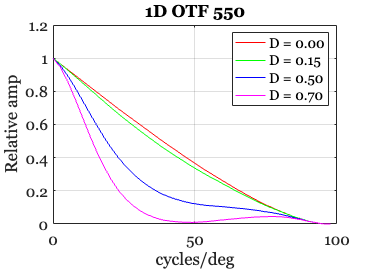

ieNewGraphWin;
for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});
    wvf1 = wvfComputePSF(wvf1);
    wvfPlot(wvf1, '1d otf angle', 'deg', wave, 100, 'nowindow');
    hold on;
    thisL{ii} = sprintf('D = %0.2f',d(ii));
end

hold off
xlabel('cycles/deg'); ylabel('Relative amp'); grid on
legend(thisL);

## The MTF with respect to angle (cpd), not space

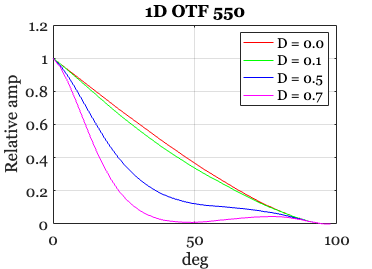

ieNewGraphWin;
for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});
    wvf1 = wvfComputePSF(wvf1);
    wvfPlot(wvf1, '1d otf angle', 'deg', wave, 100, 'nowindow');
    hold on;
    thisL{ii} = sprintf('D = %0.1f',d(ii));
end

hold off
xlabel('deg'); ylabel('Relative amp'); grid on
legend(thisL);

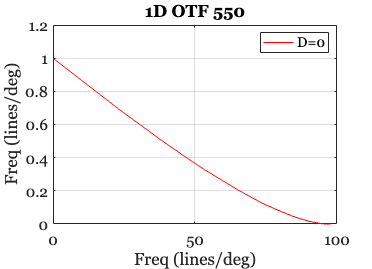

wvfPlot(wvf0, '1d otf angle', 'deg', wave, 100);
legend({'D=0'})

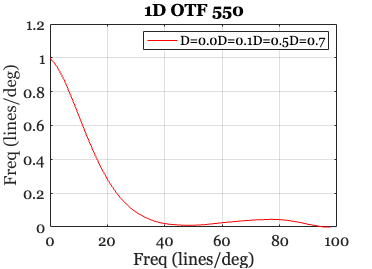


wvfPlot(wvf1, '1d otf angle', 'deg', wave, 100);
legend({sprintf('D=%1.1f',d)})



% wvfPlot(wvf0, '1d psf angle', 'sec', wave, 100);
% wvfPlot(wvf0, '2d otf', 'mm', wave, 500)

## Using human WVF, the impact of defocus differs

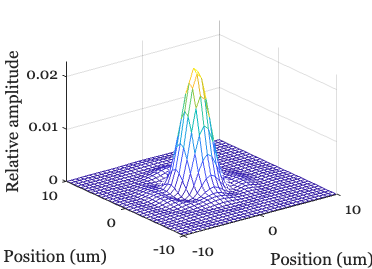

pupilDiameterMM = 3;
zCoefs = wvfLoadThibosVirtualEyes(pupilDiameterMM);
wave = 550;
umPerDegree = 300;
% Create wavefront parameters. Be sure to set both measured and
% calc pupil size.
wvfP = wvfCreate('calc wavelengths', wave, 'zcoeffs', zCoefs, ...
    'name', sprintf('human-%d', pupilDiameterMM), ...
    'umPerDegree', umPerDegree);
wvfP = wvfSet(wvfP, 'measured pupil size', pupilDiameterMM);
wvfP = wvfSet(wvfP, 'calc pupil size', pupilDiameterMM);
wvfP = wvfComputePSF(wvfP);
wvf0 = wvfP;
wvfPlot(wvf0,'psf','um',wave,10);

## Same MTF plot as above

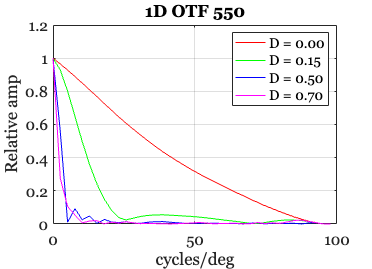

ieNewGraphWin;
for ii=1:length(d)
    wvf1 = wvfSet(wvf0,'zcoeffs',d(ii),{'defocus'});
    wvf1 = wvfComputePSF(wvf1);
    wvfPlot(wvf1, '1d otf angle', 'deg', wave, 100, 'nowindow');
    hold on;
    thisL{ii} = sprintf('D = %0.2f',d(ii));
end

hold off
xlabel('cycles/deg'); ylabel('Relative amp'); grid on
legend(thisL);